# Create Simple Image Classification Network Using Deep Network Designer

This example shows how to create and train a simple convolutional neural network for deep learning classification using Deep Network Designer. Convolutional neural networks are essential tools for deep learning and are especially suited for image recognition.

In this example, you: 

- Import image data.

- Define the network architecture.

- Specify training options.

- Train the network.

## Load Data

Load the digit sample data as an image datastore. The `imageDatastore` function automatically labels the images based on folder names. The data set has 10 classes and each image in the data set is 28-by-28-by-1 pixels. 

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

Open Deep Network Designer. Create a network, import and visualize data, and train the network using Deep Network Designer.

deepNetworkDesigner

To create a blank network, pause on **Blank Network** and click **New**. 

To import the image datastore, select the **Data** tab and click **Import Data** > **Import Image Data**. Select `imds` as the data source. Set aside 30% of the training data to use as validation data. Randomly allocate observations to the training and validation sets by selecting **Randomize**.

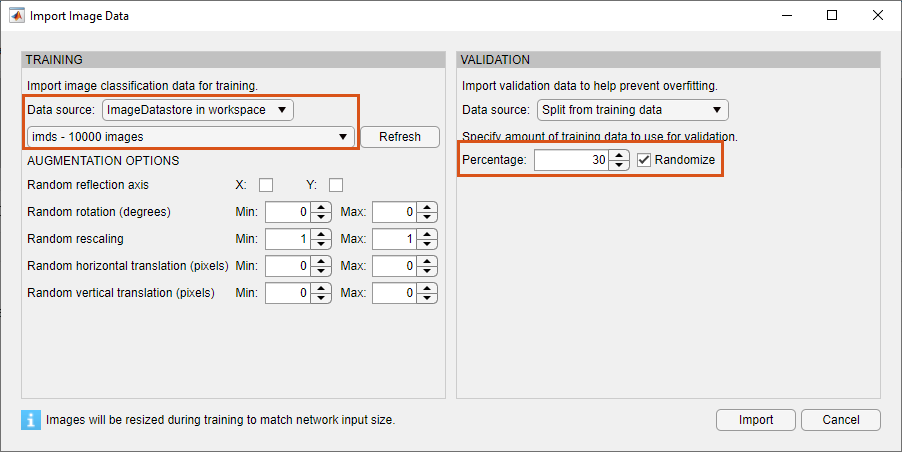

Import the data by clicking **Import**.

## Define Network Architecture

In the **Designer** pane, define the convolutional neural network architecture. Drag layers from the **Layer Library** and connect them. To quickly search for layers, use the **Filter layers** search box in the **Layer Library** pane. To edit the properties of a layer, click the layer and edit the values in the **Properties** pane.

Connect layers in this order:

- `imageInputLayer` with the `InputSize` property set to `28,28,1`

- `convolution2dLayer`

- `batchNormalizationLayer`

- `reluLayer`

- `fullyConnectedLayer` with the `OutputSize` property set to `10`

- `softmaxLayer`

- `classificationLayer`

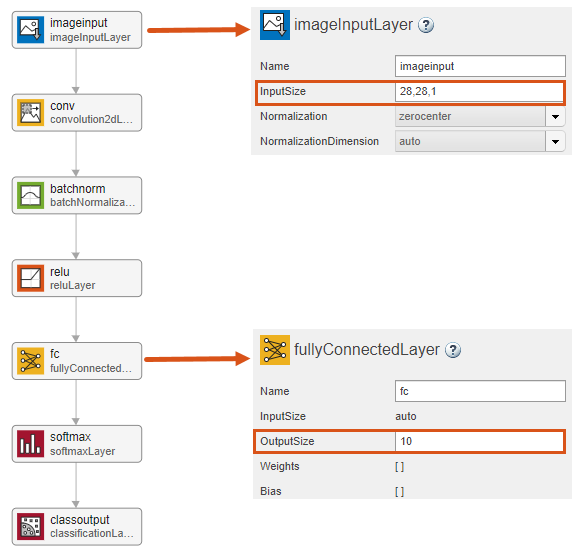

For more information about deep learning layers, see [List of Deep Learning Layers](docid:nnet_ug#mw_25a9e4c2-614f-48b9-97e2-bbdd7aaf906f).

## Train Network

Specify the training options and train the network.

On the **Training** tab, click **Training Options**. For this example, set the maximum number of epochs to 5 and keep the other default settings. Set the training options by clicking **Close**. For more information about training options, see [Set Up Parameters and Train Convolutional Neural Network](docid:nnet_ug#bvojrfv).

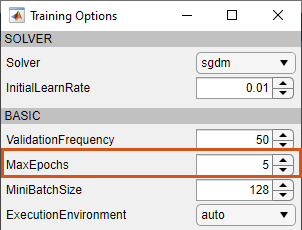

Train the network by clicking **Train**.

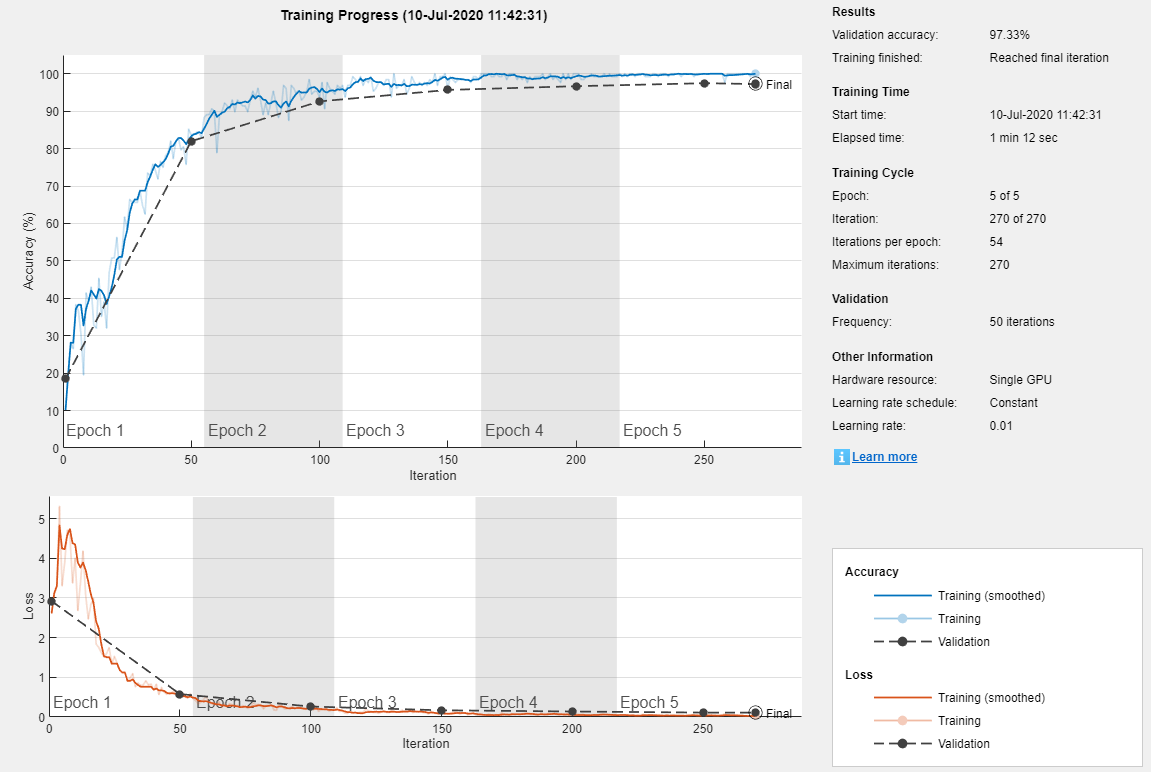

The accuracy is the fraction of labels that the network predicts correctly. In this case, more than 97% of the predicted labels match the true labels of the validation set.

To export the trained network to the workspace, on the **Training** tab, click **Export**.

For next steps in deep learning, you can try using pretrained networks for other tasks. Solve new classification problems on your image data with transfer learning. For example, see [Get Started with Transfer Learning](docid:nnet_gs#mw_e7f28092-4f41-4d94-9820-daffd2145d72). To learn more about pretrained networks, see [Pretrained Deep Neural Networks](docid:nnet_ug#bvf9ych-1).

*Copyright 2020 The MathWorks, Inc.*